-     Fie $f:[-2\pi,2\pi] \rightarrow \mathbb{R}, f(x)=sin(x^2)$. Fie setul de noduri $\{x_k, k=\overline{0,9}\}$Cebisev de peta I. Fie $t=\frac{\pi}{5}$. Se cer:

a. Reprezentati grafic functia f impreuna cu polinoamele de interpolare Lagrange si Hermite pentru acestea, pe acelasi grafic.

b. Aproximati $f(t)$ cu ajutorul polinoamelor de la subpunctul a.

c. Pentru fiecare interpolant, evaluati teoretic (cu ajutorul restului) si practic (comparand valorile functiei returnate de MATLAB cu valorile polinoamelor de interpolare).

Solutie:

(a)

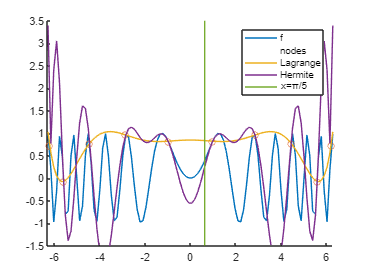

f = @(x) sin(x.*x);
df = @(x) cos(x.*x)*2.*x;
c = chebNodes(10, -2*pi, 2*pi);
x = c;
y = f(x);
dy = df(x);

graph_x = linspace(-2*pi,2*pi);
lagrange_y = LagrangeClassic(x, y, graph_x);
hermite_y = interpolareHermiteWithDerivative(x,y,dy, graph_x);


clf; hold on;
plot(graph_x, f(graph_x))
scatter(x, y)
plot(graph_x, lagrange_y)
plot(graph_x, hermite_y)
plot([pi/5, pi/5],[-1.5,3.5])
ylim([-1.5,3.5])
legend("f", "nodes", "Lagrange", "Hermite", "x=\pi/5")
hold off;

(b)

t = pi/5;
f_t = f(t)

f_t = 0.3846

lagrange_t = LagrangeClassic(x,y, t)

lagrange_t = 0.8353

hermite_t = interpolareHermiteWithDerivative(x,y,dy, t)

hermite_t = 0.2454

(c)

Masurarea teoretica erorii (Lagrange):

**(Teorema)** Daca $x_0,\ldots,x_m$ sunt $m+1$ noduri distincte in internalul $[a,b]$ si $f \in C^{n+1}[a,b]$, atunci pentru fiecare $x\in[a,b]$exista un numar $\xi(x)\in[a,b]$ astfel incat


$$f(x) = L_m f(x) + \frac{f^{(m+1)}(\xi(x))}{(m+1)!}(x-x_0)\ldots(x-x_m)$$


Dorim o margine superioara pentru eroarea 


$$err(x) = \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}(x-x_0)\ldots(x-x_m) \right| \leq \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right|\left|(x-x_0)\right|\ldots\left|(x-x_m) \right|$$



$$\leq \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right|
((x-x_1)(x_m-x))\cdot((x-x_2)(x_{m-1}-x))\cdot...
\\
 \leq \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right| \left(\frac{x_m-x_1}{2}\right)^2 \left(\frac{x_2-x_{m-1}}{2}\right)^2\ldots
\left(\frac{x_{[m/2]}-x_{[m/2]+1}}{2}\right)^2
$$


In particular, $m=9, x_i=2\pi cos\left(\frac{(2i+1)\pi}{n}\right), i=\overline{0,9}$

syms x
f = f(x)

$$f = \sin\left(x^{2}\right)$$

d10f = diff(f, 10);
err1 = d10f/factorial(10)

$$err1 = \frac{\cos\left(x^{2}\right)}{120}-\frac{x^{4}\,\cos\left(x^{2}\right)}{9}+\frac{2\,x^{8}\,\cos\left(x^{2}\right)}{315}-\frac{x^{2}\,\sin\left(x^{2}\right)}{12}+\frac{2\,x^{6}\,\sin\left(x^{2}\right)}{45}-\frac{4\,x^{10}\,\sin\left(x^{2}\right)}{14175}$$


$$\rightarrow \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right| = |err1(\xi(x))| \le 
\frac{1}{120} + \frac{(2\pi)^4}{9}+ \frac{2(2\pi)^8}{315} + \frac{(2\pi)^2}{12} +  
\frac{2(2\pi)^6}{45}+\frac{4(2\pi)^{10}}{14175}$$


M1 = 1/120+(2*pi)^4/9 + 2*(2*pi)^8/315 + (2*pi)^2/12 + 2*(2*pi)^6/45 + 4*(2*pi)^10/14175

M1 = 4.5394e+04


$$\rightarrow |err1(\xi(x))| \le 5\cdot10^4$$


M2 = (((c(1)-c(10))/2)*((c(2)-c(9))/2)*((c(3)-c(8))/2)*((c(4)-c(7))/2)*((c(5)-c(6))/2))^2

M2 = 1.8730e+05

$\rightarrow$eroarea teoretica pentru aproximarea Lagrange este de ordinul $10^9
$ (?)

Eroarea practica Lagrange:

abs_err = max(double(subs(f, graph_x)) - lagrange_y)

abs_err = 0.9822

Masurarea teoretica erorii (Hermite):

Dorim o margine superioara pentru eroarea 


$$err(x) = \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}(x-x_0)^2\ldots(x-x_m)^2 \right| \leq \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right|\left|(x-x_0)\right|^2\ldots\left|(x-x_m) \right|^2$$



$$\leq \left| \frac{f^{(m+1)}(\xi(x))}{(m+1)!}\right|
((x-x_0)\ldots(x-x_m))^2

$$


In particular, $m=9, x_i=2\pi cos\left(\frac{(2i+1)\pi}{n}\right), i=\overline{0,9}$

M1 = 1/120+(2*pi)^4/9 + 2*(2*pi)^8/315 + (2*pi)^2/12 + 2*(2*pi)^6/45 + 4*(2*pi)^10/14175

M1 = 4.5394e+04


$$\rightarrow |err1(\xi(x))| \le 5\cdot10^4$$


M2 = M2^2 % ???

M2 = 3.5080e+10

Eroarea practica Hermite:

abs_err = max(double(subs(f, graph_x)) - hermite_y)

abs_err = 2.9346

function lk = L(nodes,k)
    % polinomul fundamental L_k pentru nodurile nodes_1,...,nodes_n        
    % lk = prod_{j,j!=k}(x-xj)/prod_{j,j!=k}(xk-xj)
    m = size(nodes,2);
    roots = cat(2, nodes(1:k-1), nodes(k+1:m));    
    p = poly(roots);
    lk = p ./ polyval(p,nodes(k));
end

function u = LagrangeClassic(x,y,t)
    m = size(x,2);
    n = size(t,2);   
    pf = zeros('like', x);
    for k=1:m               
        pf = pf + (L(x,k) .* y(k));
    end      
    u = polyval(pf,t);
end

function c = chebNodes(n,a,b)
    c = (a+b)/2 + (b-a)/2*cos((2*[1:n]-1)*pi/(2*n));
end

function [ H, dH] = interpolareHermiteWithDerivative( x, f, fd, X )
	coefs=dif_div_duble(x,f,fd);
    
    coefs=coefs(1,:);
    
	z=repelem(x,2);
	H=X; 
	dH=X;
    for k=1:length(X)
          P=1; DP=0; 
      H(k)=coefs(1)*P; dH(k)=0;
      
      for i=2:length(coefs)
       DP=DP*(X(k)-z(i-1))+P;
       P=P*(X(k)-z(i-1));
       H(k)=H(k)+coefs(i)*P;
       dH(k)=dH(k)+coefs(i)*DP;
      end
    end
end

function T=dif_div_duble(x,f,df)
	T=NaN(2*length(x));
	z=repelem(x,2);
	T(:,1)=repelem(f,2);
	T(1:2:end-1,2)=df;
	T(2:2:end-2,2)=diff(f)./diff(x);
	for j=3:length(z)
		 T(1:end-j+1,j)=diff(T(1:end-j+2,j-1))./(z(j:end)-z(1:end-j+1))';
    end
end